# Charge-to-Mass Ratio for Electrons Lab

*Steven Henderson*

**Equations**


$$\begin{array}{l}
F=\frac{{\mathrm{mv}}^2 }{r}=\mathrm{qvB}\\
v=\frac{\mathrm{qrB}}{m}\\
v=\sqrt{\frac{2\mathrm{qV}}{m}}\\
V=\frac{v^2 m}{2q}=\frac{q}{2m}{\left(\mathrm{rB}\right)}^2 \\
r^2 =2\frac{\mathrm{mV}}{{\mathrm{qB}}^2 }\\
B=\mu_0 \mathrm{NI}\frac{R_c^2 }{{\left(R_c^2 +{\left(\frac{d}{2}\right)}^2 \right)}^{\frac{3}{2}} },\mathrm{where}\;d=R_c 
\end{array}$$


## Part 1: Collecting Data

To start, we will collect the the radius (in amount of rungs) of the electron arc caused by the magnetic field due to the current in the Hemlotz coils. We will collect the current constant while we change the voltage to the heater therefore, changing the velocity of the electrons. Uncertainity for the voltages and currents will be determined by the fluctuations in the measurements. Needed values such as the radius of the coils will be taken while the number of turns was given in the lab manual.

% Taken Data
V = [200, 213. 220, 239, 251, 265, 276;...
     200, 217, 227, 240, 252, 263, 279;...
     221, 200, 241, 257, 266, 216, 282] ; % Voltages of anode (V)
V_uncer = [7, 3, 2, 5, 3, 1, 2;...
           4, 1, 2, 3, 1, 1, 3;...
           3, 5, 3, 3, 2, 1, 1] ; 
I = [-1.5, -1.53, -1.51, -1.54, -1.59, -1.67, -1.72;...
     -0.21, -0.3, -0.38, -0.48, -0.6, -0.63, -0.78;...
     -1.14, -1.01, -1.19, -1.28, -1.4, -1.08, -1.5]; % Current of Hemlotz Coils (A)
I_uncer = [0.02, 0.008, 0.002, 0.002, 0.006, 0.012, 0.012;...
           0.004, 0.01, 0.008, 0.009, 0.007, 0.007, 0.004;...
           0.008, 0.008, 0.008, 0.012, 0.008, 0.004, 0.005] ;
rung = [3, 3.4, 3.25] ; % Rung where the beam hits
rung_uncer = [0.1, 0.2, 0.01] ;
WV = -0.1 ;
R = 15.1 / 100 ; % Radius of Hemlotz Coils (m)
R_uncer = 0.25 / 100 ;
d = 10 / 100; % Distance between coils and cathode (m) 
d_uncer = 0.25 / 100 ;
mu = 4*pi*10^(-7) ; % Known value of mu_naught
N = 124 ; % Number of turns in the Coils given in lab manual
%

## Part 2: Parsing Data

For this part we will take the data that we recorded and plug them into their respective equations to find the values we need to measure the charge-mass ratios. Equations are found below,


$$B=\mu_0 \mathrm{NI}\frac{R_c^2 }{{\left(R_c^2 +{\left(\frac{d}{2}\right)}^2 \right)}^{\frac{3}{2}} }$$



$$\sigma_B =\sqrt{{\left(\frac{{\mathrm{NR}}_c^2 \mu_0 }{{\left({\left(\frac{d}{2}\right)}^2 +R_c^2 \right)}^{\frac{5}{2}} }\right)}^2 \sigma_I^2 +{\left(-\frac{\mathrm{IN}\mu_0 R\left(2R^2 -d^2 \right)}{2{\left(R_c^2 +{\left(\frac{d}{2}\right)}^2 \right)}^{\frac{5}{2}} }\right)}^2 \sigma_R^2 +{\left(-\frac{3{\mathrm{INR}}_c^2 \mu_0 d}{4{\left({\left(\frac{d}{2}\right)}^2 +{R_c }^2 \right)}^{\frac{5}{2}} }\right)}^2 \sigma_d^2 }$$



$$\begin{array}{l}
l\;\mathrm{is}\;\mathrm{the}\;\mathrm{linear}\;\mathrm{coefficient}\;\mathrm{that}\;V\;\mathrm{is}\;\mathrm{plotted}\;\mathrm{against}\\
l=\frac{{\left(\mathrm{rB}\right)}^2 }{2}\\
\sigma_l =\sqrt{{\left({r^2 B} \right)}^2 \sigma_B^2 +{\left({\mathrm{rB}}^2 \right)}^2 \sigma_r^2 }
\end{array}$$


% Finding needed values using formulas above
D = rung*(20/1000) ; % Diamter of arc (m)
D_uncer = rung_uncer*(20/1000) ;

r = D / 2 ; % Radius of arc (m)
r_uncer = D_uncer / 2 ;

B = mu*N*I*(R^2/(R^2+(d/2)^2)^(3/2)) ; % Magnetic field (T)
B_uncer = sqrt(((N*R^2*mu)/((d/2)^2 + R^2)^(5/2)).^2*I_uncer.^2 + ((-I*N*mu*(2*R^2-d^2))/(2*(R^2+(d/2)^2)^(5/2))).^2*R_uncer.^2+((-3*I*N*R^2*mu*d)/(4*((d/2)^2+R)^(5/2))).^2*d_uncer.^2) ;
%

## Part 3: Finding Fits and Plotting

This part is just finding the fits for the values of,


$$V\;\mathrm{and}\;\frac{{\left(\mathrm{rB}\right)}^2 }{2}$$


and comparing their slopes to the value of,


$$\frac{q}{m}=1\ldotp 758820\times {10}^{11} \;\frac{C}{\mathrm{kg}}$$


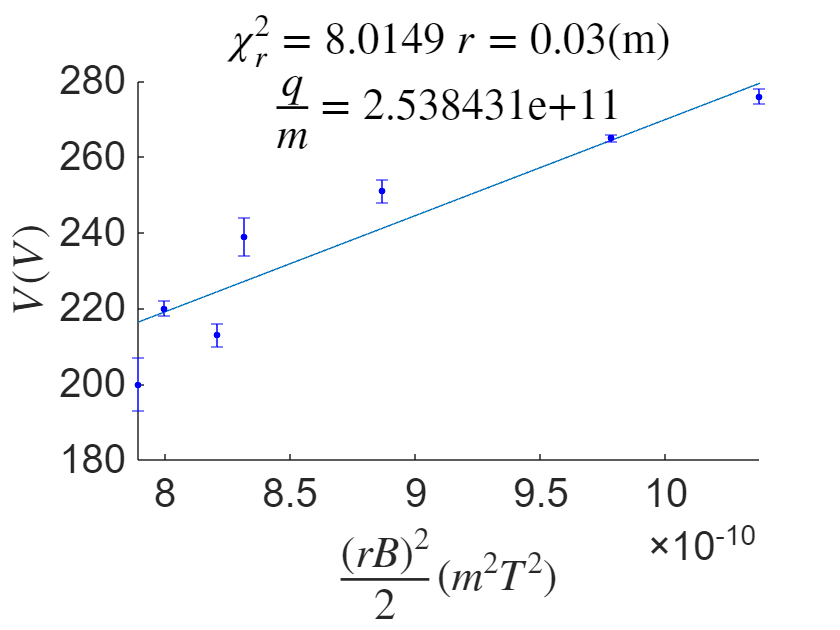

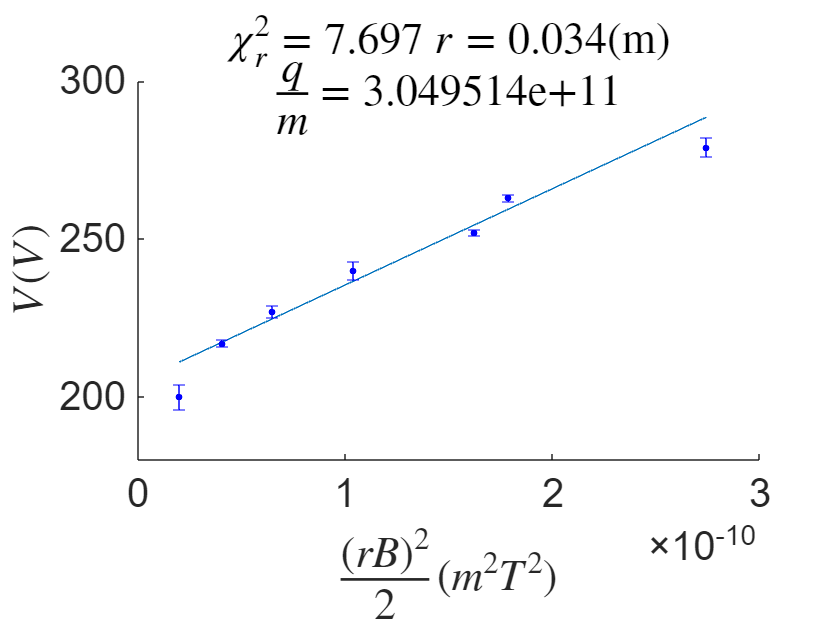

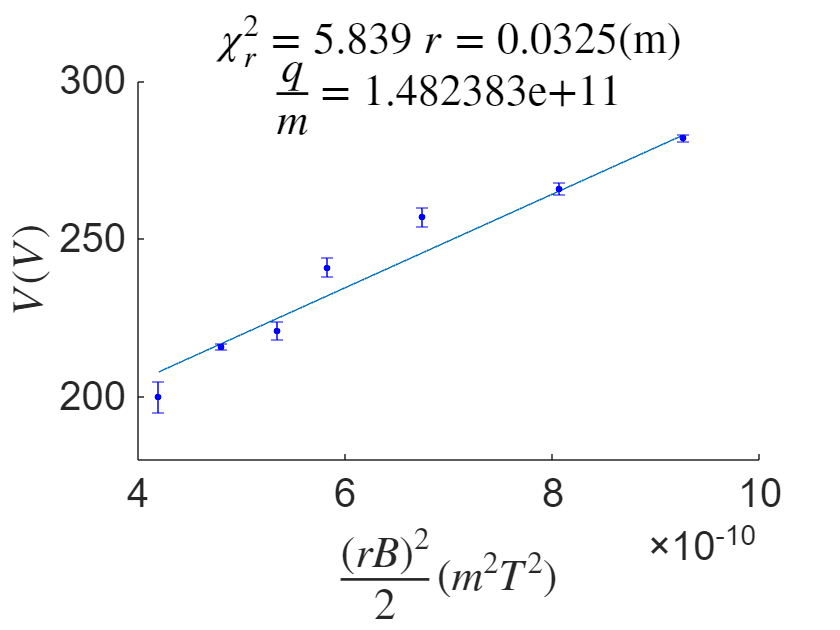

actual_qm = 1.758820e11 ; % actual value of q/m
qms = [] ;
chirs = [] ;
sigmas = [];
% Plotting data and finding fits
for i = 1:length(r)
    linear_coeff = 0.5*(r(i).*B(i, :)).^2 ; % Linear coefficient used for finding fit (mT)^2
    f = wlsfit(linear_coeff, V(i, :), V_uncer(i, :)) ; % Fit for V vs. linear coefficient
    chi = findChi(linear_coeff, V(i, :), V_uncer(i, :), f(2), f(1)) ; % Chi values of the fit
    qms(end+1) = f(2)  ;% add q/m value to array for averaging
    chirs(end+1) = chi(2) ; % add chi reduced value to array for averaging
    sigmas(end+1) = f(4) ; % add uncertainity of the slope e.i. the q/m value measured
    % Plot data
    figure
    fit_line = f(1) + f(2)*linear_coeff ;
    hold on
    plot(linear_coeff, fit_line) ;
    errorbar(linear_coeff, V(i, :), V_uncer(i, :), 'b.', 'MarkerSize', 10) ;
    hold off
    set(gca, 'Fontsize', 20) ;
    xlabel('$\frac{(rB)^2}{2} (m^2T^2)$', 'Interpreter', 'latex') ;
    ylabel('$V (V)$', 'Interpreter', 'latex')
    title(['$\chi^2_r=$', num2str(chi(2)), '  $r=$', num2str(r(i)), '(m)'],'Interpreter', 'latex')
    s = subtitle(['$\frac{q}{m}=$', sprintf('%10e',f(2))], 'Interpreter', 'latex') ;
    s.Position(2) = s.Position(2) - 22 ; 
    % Do I need a legend here?
end

% Find average
qm = mean(qms) ; % Averaged q/m 
chir = mean(chirs) ; % Average chi square reduced 
disp(['q/m=', sprintf('%10e',qm), '| chi_r^2=', num2str(chir)]) ;

q/m=2.356776e+11| chi_r^2=7.1836


rungs = [3, 3.5, 3.25] ;

rungs =     3.0000    3.5000    3.2500


for i = 1:length(sigmas)
    sigma_away = abs(actual_qm - qms(i))/sigmas(i) ;
    disp(['for the arc hitting rung ', num2str(rungs(i)), ' | q/m=', num2str(qms(i)), ' | sigma away=', num2str(sigma_away)])
end

for the arc hitting rung 3 | q/m=253843111426.7404 | sigma away=8.389
for the arc hitting rung 3.5 | q/m=304951389746.3455 | sigma away=16.0782
for the arc hitting rung 3.25 | q/m=148238339249.2406 | sigma away=9.1702


## Part 4: Analysis

Of the three graphs we can see that the third is the closest and has the best chi-squared reduced value. We see a value of $\frac{q}{m}=1\ldotp 482\times {10}^{11} \frac{C}{\mathrm{kg}}$ and a chi-square value of $\chi_r^2 =5\ldotp 839$ which means it is a good fit but, the uncertainities could be higher. This most likely comes from the fact that the uncertainities only come from the voltage reading which was only measured based on the fluctutations in readings. To get a better chi-square value I could find a way to incorporate the uncertainity of $\frac{{\left(\mathrm{rB}\right)}^2 }{2}$. The average value of $\frac{q}{m}=2\ldotp 35\times {10}^{11}$ with a $\chi_r^2 =7\ldotp 1836$ which has a poor chi square reduced value for the same reasons as before. Comparing with the uncertainities we find that the measurements done with keeping the arc hitting rung 3 is the most accurate with it being 8.389 sigma away. The worst measurement was with keeping the rung as 3.5, with a sigma away of 16.08. The possible reason for these bad values is most likely from the rung measurements as the data was taken in a dark room with low visibilty and the in between rung measurements may have been inaccurate as there are no in between markers on the rungs. If the rung uncertainity was taken into account these value will probably show a lot better results.

## Functions used for finding fits and chi squares.

% Function for calculating linear fit by weighted least squares
function fit = wlsfit(x, y, y_uncer)
    weights = 1 ./ y_uncer.^2 ;
    delta = sum(weights)*sum(weights.*(x.^2)) - (sum(weights.*x))^2 ;
    A = (sum(weights.*x.^2)*sum(weights.*y) - sum(weights.*x)*sum(weights.*x.*y)) / delta ;
    B = (sum(weights)*sum(weights.*x.*y) - sum(weights.*x)*sum(weights.*y)) / delta ; 
    A_err = sqrt(sum(weights.*x.^2) / delta) ;
    B_err = sqrt(sum(weights) / delta) ;
    % Return in form fit = A + Bx
    fit = [A, B, A_err, B_err] ;
end

% Function for finding chi-square and reduced chi-square with poly1 as the
% fit
function chi = findChi(xdata, ydata, ydataerr, slope, offset)
    % chisq inputs: xdata, ydata, ydata errors, best fit slope and offset
    % outpus: chi2 and reduced chi2
    weights = 1./(ydataerr.^2) ; % find weights from errors
    myfit = slope.*xdata + offset; % find best linear fit
    chi2 = sum(((ydata-myfit).^2).*weights) ;
    n = size(xdata,2) ; % # of data elements
    rchi2 = chi2/(n-2) ; % # of degrees of freedom
    chi = [chi2, rchi2] ;
end